xt_scg=x2';
yt_scg=y2';
hiddenLayerSize=44;
scg=fitnet(hiddenLayerSize,'trainscg');

Not enough input arguments.

Error in mse (line 2)
mseValue = mean((ytrue-ypred).^2,"omitnan");

Error in network>new_network (line 142)
net.performParam = mse('defaultParam');

Error in network (line 71

scg.divideFcn = 'divideind';
scg.divideParam.trainInd = tr_lm.trainInd;
scg.divideParam.valInd = tr_lm.valInd;
scg.divideParam.testInd= tr_lm.testInd;
[scg,tr_scg]=train(scg,xt_scg,yt_scg);

**Performence**

Training set

Y_scg=scg(xt_scg(:,tr_scg.trainInd));
Yt_scg=yt_scg(:,tr_scg.trainInd);
yTrain_scg=(Y_scg'.*(max(y)-min(y))+min(y))';
yTrainTrue_scg=(Yt_scg'.*(max(y)-min(y))+min(y))';
perf_P_scg=rMetrics(yTrainTrue_scg(1,:),yTrain_scg(1,:));
perf_Nu_scg=rMetrics(yTrainTrue_scg(2,:),yTrain_scg(2,:));
row_names_scg=array2table({'Pressure_ratio';'Nusselt ratio'});
T_scg_train=cat(1,perf_P_scg,perf_Nu_scg);
T_scg_train=cat(2,row_names_scg,T_scg_train)

T_scg_train = 2×6 table
           Var1             mae          mse         rmse        Rsq       mape 
    __________________    ________    _________    ________    _______    ______

    {'Pressure_ratio'}    0.039627    0.0031054    0.055726    0.97427    3.4681
    {'Nusselt ratio' }    0.027951    0.0015093    0.038849     0.9341    3.2383


Validation set

Y_val_scg=scg(xt_scg(:,tr_scg.valInd));
Yt_val_scg=yt_scg(:,tr_scg.valInd);
yVal_scg=(Y_val_scg'.*(max(y)-min(y))+min(y))';
yValTrue_scg=(Yt_val_scg'.*(max(y)-min(y))+min(y))';
perf_P_scg=rMetrics(yValTrue_scg(1,:),yVal_scg(1,:));
perf_Nu_scg=rMetrics(yValTrue_scg(2,:),yVal_scg(2,:));
row_names_scg=array2table({'Pressure_ratio';'Nusselt ratio'});
T_scg_val=cat(1,perf_P_scg,perf_Nu_scg);
T_scg_val=cat(2,row_names_scg,T_scg_val)

T_scg_val = 2×6 table
           Var1             mae          mse         rmse        Rsq       mape 
    __________________    ________    _________    ________    _______    ______

    {'Pressure_ratio'}    0.038995    0.0029408    0.054229    0.97183    3.4592
    {'Nusselt ratio' }    0.028476    0.0016027    0.040034    0.92993     3.328


**Plot**

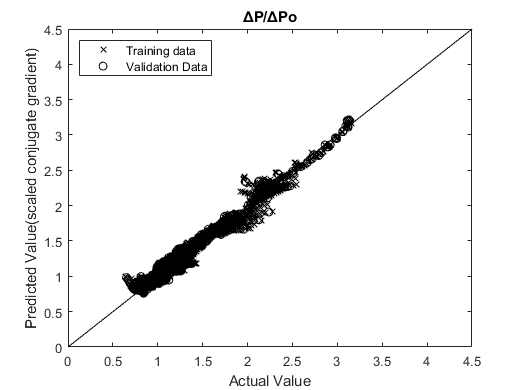

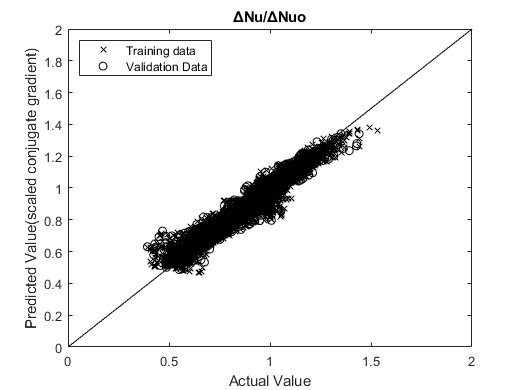

for i=1:2
    figure()
    set(gca,'box','on')
    plot(yTrainTrue_scg(i,:),yTrain_scg(i,:),'x','color','k');hold on;
    plot(yValTrue_scg(i,:),yVal_scg(i,:),'o','color','k');
    plot(0:5,0:5,'color','k');
    if i==1
        xlim([0 4.5])
        ylim([0 4.5])
    else
        xlim([0 2])
        ylim([0 2])
    end
    legend('Training data','Validation Data','','location','northwest')
    ylabel('Predicted Value(scaled conjugate gradient)')
    xlabel('Actual Value')
    if i==1
        title('ΔP/ΔPo');
    else
        title('ΔNu/ΔNuo');
    end
    hold off;
    if i==1
        Plot_SCG_5=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔP÷ΔPo.bmp');
        saveas(gcf,Plot_SCG_5)
    else
        Plot_SCG_5=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔNu÷ΔNuo.bmp');
        saveas(gcf,Plot_SCG_5)
    end
    
end

**Optimization**

%select all and press ctrl+T to enable section
hiddenLayerNo=[1,2,3];
for i=1:50
    hiddenLayerSize=i;
    %defining the architecture of the Ann
    scg=fitnet(hiddenLayerSize,'trainscg');
    scg.divideFcn = 'divideind';
    scg.divideParam.trainInd = tr_lm.trainInd;
    scg.divideParam.valInd = tr_lm.valInd;
    scg.divideParam.testInd= tr_lm.testInd;

    %training of Ann
    [scg,tr_scg]=train(scg,xt_scg,yt_scg);
    
    
    Y_opt_scg=scg(xt_scg(:,tr_scg.trainInd));
    Yt_opt_scg=yt_scg(:,tr_scg.trainInd);
    Yv_opt_scg=scg(xt_scg(:,tr_scg.valInd));
    Yvt_opt_scg=yt_scg(:,tr_scg.valInd);
    

    yTrain_scg=(Y_opt_scg'.*(max(y)-min(y))+min(y))';
    yTrainTrue_scg=(Yt_opt_scg'.*(max(y)-min(y))+min(y))';
    yVal_scg=(Yv_opt_scg'.*(max(y)-min(y))+min(y))';
    yValTrue_scg=(Yvt_opt_scg'.*(max(y)-min(y))+min(y))';
   
    %rmse
    for j=1:2
        rms_train_scg(i,j)=sqrt(mean((yTrain_scg(j,:)-yTrainTrue_scg(j,:)).^2));
    end   
    for j=1:2
        rms_val_scg(i,j)=sqrt(mean((yVal_scg(j,:)-yValTrue_scg(j,:)).^2));
    end

    %r2
    for j=1:2
        r2_train_scg(i,j)=1 - (sum(((yTrainTrue_scg(j,:) - yTrain_scg(j,:)).^2),2)/sum(((yTrainTrue_scg(j,:) - mean(yTrainTrue_scg(j,:),2)).^2),2));
    end   
    for j=1:2
        r2_val_scg(i,j)=1 - (sum(((yValTrue_scg(j,:) - yVal_scg(j,:)).^2),2)/sum(((yValTrue_scg(j,:) - mean(yValTrue_scg(j,:))).^2),2));
    end
    
    %mape

    for j=1:2
        mape_train_scg(i,j)=mean(abs((yTrainTrue_scg(j,:)-yTrain_scg(j,:))./yTrainTrue_scg(j,:)),2).*100;
    end   
    for j=1:2
        mape_val_scg(i,j)=mean(abs((yValTrue_scg(j,:)-yVal_scg(j,:))./yValTrue_scg(j,:)),2).*100;
    end
    
   name_scg{i} = ['Hidden Layer size: ' num2str(i,'%d')];
   Ta_scg=array2table(rms_train_scg,"VariableNames",{'RMSE(ΔP/delPo)','RMSE(ΔNu/ΔNuo)'});
   Ta_scg.Properties.RowNames=name_scg;
   Tb_scg=array2table(rms_val_scg,"VariableNames",{'RMSE(ΔP/delPo)','RMSE(ΔNu/ΔNuo)'});
   Tb_scg.Properties.RowNames=name_scg;
end

%select all and press ctrl+T to enable section
Ta_scg

Ta_scg = 50×2 table
                             RMSE(ΔP/delPo)    RMSE(ΔNu/ΔNuo)
                             ______________    ______________

    Hidden Layer size: 1         0.32531           0.10973   
    Hidden Layer size: 2         0.15626           0.11057   
    Hidden Layer size: 3         0.14748           0.11113   
    Hidden Layer size: 4         0.10471          0.099251   
    Hidden Layer size: 5         0.10874          0.093321   
    Hidden Layer size: 6         0.11002          0.076991   
    Hidden Layer size: 7         0.10921          0.094557   
    Hidden Layer size: 8         0.10364          0.098728   
    Hidden Layer size: 9         0.10003          0.060613   
    Hidden Layer size: 10       0.089504          0.055506 

Tb_scg

Tb_scg = 50×2 table
                             RMSE(ΔP/delPo)    RMSE(ΔNu/ΔNuo)
                             ______________    ______________

    Hidden Layer size: 1         0.31594           0.10884   
    Hidden Layer size: 2         0.15368           0.11078   
    Hidden Layer size: 3         0.14885           0.11107   
    Hidden Layer size: 4         0.10339          0.098929   
    Hidden Layer size: 5         0.10676          0.092514   
    Hidden Layer size: 6         0.11287          0.079071   
    Hidden Layer size: 7         0.11142          0.098762   
    Hidden Layer size: 8         0.10631          0.099344   
    Hidden Layer size: 9         0.10696          0.062109   
    Hidden Layer size: 10       0.088039          0.055222 

writetable(Ta_scg,'D:/Matlab Drive/Research/Table/Performence_scg(training).xlsx','Sheet',1)
writetable(Tb_scg,'D:/Matlab Drive/Research/Table/Performence_scg(validation).xlsx','Sheet',1)

**Select Optimum no of neuron in hidden layer(rmse)**

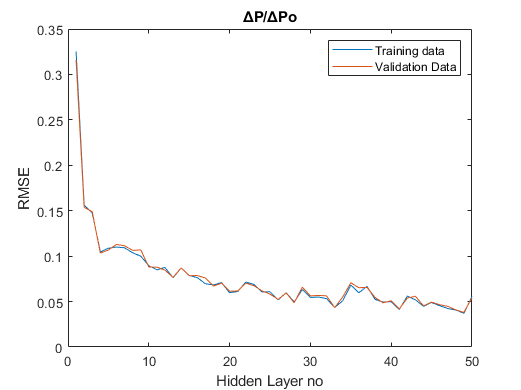

%select all and press ctrl+T to enable section
%pressure
plot(1:i,rms_train_scg(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔP/ΔPo')
plot(1:i,rms_val_scg(:,1));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔP÷ΔPo_optimisation(rmse).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

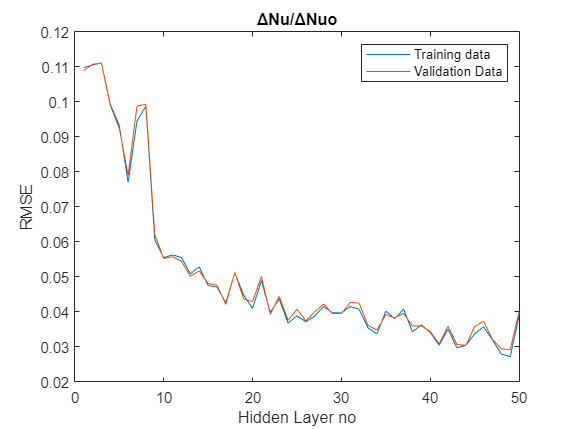


%Nusselt
plot(1:i,rms_train_scg(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔNu/ΔNuo')
plot(1:i,rms_val_scg(:,2));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔNu÷ΔNuo_optimisation(rmse).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

**Select Optimum no of neuron in hidden layer(r2)**

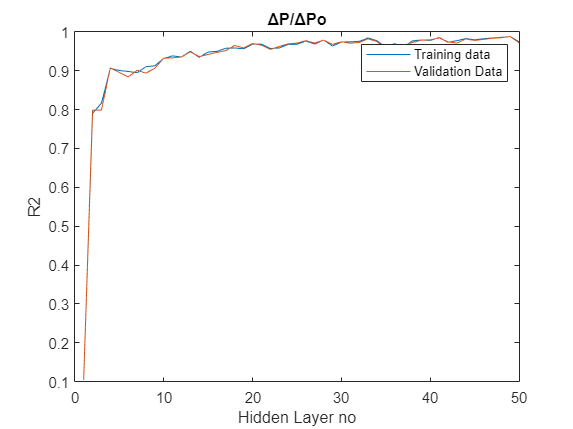

%select all and press ctrl+T to enable section
%pressure
plot(1:i,r2_train_scg(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔP/ΔPo')
plot(1:i,r2_val_scg(:,1));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔP÷ΔPo_optimisation(r2).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

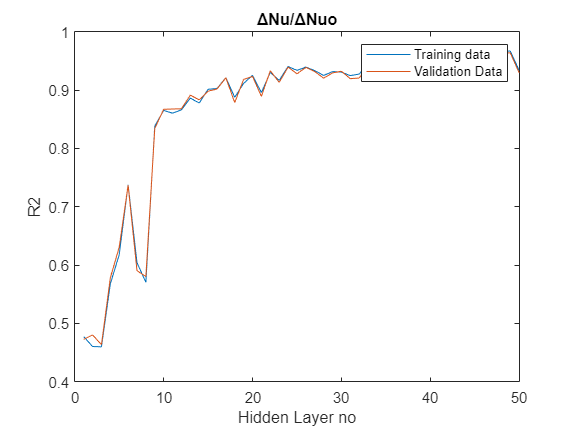


%Nusselt
plot(1:i,r2_train_scg(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔNu/ΔNuo')
plot(1:i,r2_val_scg(:,2));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔNu÷ΔNuo_optimisation(r2).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

**Select Optimum no of neuron in hidden layer(mape)**

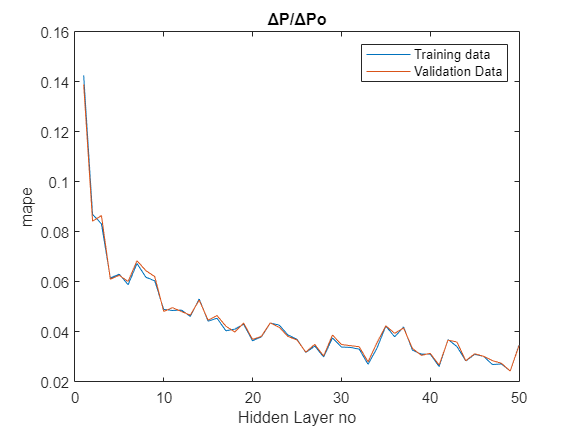

%select all and press ctrl+T to enable section
%pressure
plot(1:i,mape_train_scg(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔP/ΔPo')
plot(1:i,mape_val_scg(:,1));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔP÷ΔPo_optimisation(mape).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

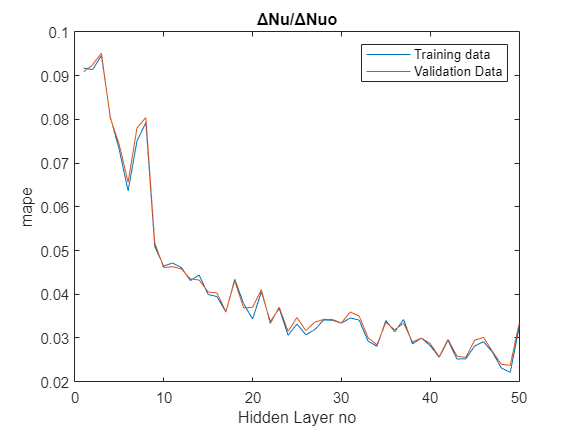


%Nusselt
plot(1:i,mape_train_scg(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔNu/ΔNuo')
plot(1:i,mape_val_scg(:,2));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔNu÷ΔNuo_optimisation(mape).bmp');
saveas(gcf,Plot_SCG_6);
hold off;